# **RS-HL-12: Multi User Design**

**Hongseok Kim**

**UT Austin Oden Institute**

**07/18/2024**

## I. Scope

- So far, we could design the MDP structure of Given network connection matrix, and could simulate multiple agent's data packet transmission process by perfect hierarchy.

- But, with perfect hierarchy, there exist unfair decisions between multiple agents. Therefore, we have to design other algorithm which make optimal decision between multiple agents' actions.

- We are using state-value and action-value dataset from original sat-to-sat connection matrix for each destination, and propagate the data transmission for given time vector. Then, serch the data packet collision.

- If there exist data packet collision, we find althernative actions from t_0 to t_collision -1 for data packet of collision. Then, quantify the minimum difference of action value from t_0 to t_collision and change the value.

- Then, change the policy which have minimum difference of action value. 

- Change the path of the agent and check there exist collision in the future. 

- In case of the different destination, we will consider satellite will downlink the packet data right after it receive the data. So we can use that satellite after the transmission. - or we can make another conidtion: the data packet at the final destination will stay for a while and other data packet cannot reach to that location,

## II. Traffic Police Algorithm

- Create Action Value Vector and save it. - (Done) 

### II.1 Load the SAT-to-SAT  / GS-to-SAT dataset

% clear;clc;
% % Load the Satellite Contat Dataset
% addpath('~/Desktop/Redstone_Project/RS_HL/RS_HL_10_TV_MDP_Functions')
% load('/workspace/RS_Dataset/RS_HL_3_dataset.mat')

### II.2 Find Available GS for given time vector

% time_index_vector = 100:120;
% contact_info = [];
% for t = time_index_vector
% 
% [gs, sat] = find(gs_to_sat_contact_3d_matrix(:,:,t) == 1);
% time = ones(length(gs),1)*t;
% A = [gs, sat, time]; 
% 
% contact_info = [contact_info;A];
% end
% 
% scatter3(contact_info(:,1),contact_info(:,2),contact_info(:,3),'.')
% xlabel('ground station no')
% ylabel('satellite no')
% zlabel('time')
% title('contact information')
% grid on
% 
% 
% [gs_start, sat_start] = find(gs_to_sat_contact_3d_matrix(:,:,100) == 1);
% [gs_end, sat_end] = find(gs_to_sat_contact_3d_matrix(:,:,120) == 1);
% 
% 
% scatter(gs_start, sat_start,'r','.')
% hold on
% scatter(gs_end, sat_end,'blue')
% hold off
% xlabel('ground station no')
% ylabel('satellite no')
% legend('start time','end time','location','northeast')
% grid on
% 

### II.2 Run MDP for each destination

% Parameter Setting
time_index_vector = 100:120;
destination_state_1 = 38;
destination_state_2 = 3;
destination_state_3 = 11;

% Run MDP
MDP1 = runMDP(sat_to_sat_contact_3d_matrix, time_index_vector,destination_state_1);

simulation set up complete! 
Policy: 1 -> Value Iteration: 469
Policy: 2 -> Value Iteration: 14
Policy: 3 -> Value Iteration: 5
Policy: 4 -> Value Iteration: 5
Policy: 5 -> Value Iteration: 8
Policy: 6 -> Value Iteration: 10
Policy: 7 -> Value Iteration: 9
Policy: 8 -> Value Iteration: 1
Policy: 9 -> Value Iteration: 1
Policy: 10 -> Value Iteration: 1
Policy: 11 -> Value Iteration: 1


MDP2 = runMDP(sat_to_sat_contact_3d_matrix, time_index_vector,destination_state_2);

simulation set up complete! 
Policy: 1 -> Value Iteration: 423
Policy: 2 -> Value Iteration: 14
Policy: 3 -> Value Iteration: 8
Policy: 4 -> Value Iteration: 5
Policy: 5 -> Value Iteration: 5
Policy: 6 -> Value Iteration: 7
Policy: 7 -> Value Iteration: 9
Policy: 8 -> Value Iteration: 3
Policy: 9 -> Value Iteration: 1


MDP3 = runMDP(sat_to_sat_contact_3d_matrix, time_index_vector,destination_state_3);

simulation set up complete! 
Policy: 1 -> Value Iteration: 428
Policy: 2 -> Value Iteration: 14
Policy: 3 -> Value Iteration: 5
Policy: 4 -> Value Iteration: 5
Policy: 5 -> Value Iteration: 5
Policy: 6 -> Value Iteration: 9
Policy: 7 -> Value Iteration: 3
Policy: 8 -> Value Iteration: 3


### II.3 User 1 Simulation

start_time = 100;
start_state_1 = 8;
start_state_2 = 38;
start_state_3 = 25;

% 
% % Run Simulation
[time_list, reward_list, state_list, state_value_list]= simulation_test(start_time,start_state_1,MDP1,time_index_vector,destination_state_1);

simulation_result_1 = [time_list, state_list, reward_list, state_value_list]

simulation_result_1 =   100.0000    8.0000         0   44.5000
  101.0000    9.0000   -1.0000   53.0000
  102.0000   10.0000   -2.0000   61.5000
  103.0000   11.0000   -3.0000   70.0000
  104.0000   37.0000  -18.0000   92.5000
  105.0000   38.0000   82.0000         0



[time_list, reward_list, state_list, state_value_list]= simulation_test(start_time,start_state_2,MDP2,time_index_vector,destination_state_2);

simulation_result_2 = [time_list, state_list, reward_list, state_value_list]

simulation_result_2 =   100.0000   38.0000         0    2.0000
  101.0000   37.0000   -1.0000   10.5000
  102.0000   36.0000   -2.0000   19.0000
  103.0000   10.0000  -17.0000   41.5000
  104.0000    9.0000  -18.0000   50.0000
  105.0000    8.0000  -19.0000   58.5000
  106.0000    7.0000  -20.0000   67.0000
  107.0000    6.0000  -21.0000   75.5000
  108.0000    5.0000  -22.0000   84.0000
  109.0000    4.0000  -23.0000   92.5000



[time_list, reward_list, state_list, state_value_list]= simulation_test(start_time,start_state_3,MDP3,time_index_vector,destination_state_3);

simulation_result_3 = [time_list, state_list, reward_list, state_value_list]

simulation_result_3 =   100.0000   25.0000         0   19.0000
  101.0000    4.0000  -15.0000   41.5000
  102.0000    5.0000  -16.0000   50.0000
  103.0000    6.0000  -17.0000   58.5000
  104.0000    7.0000  -18.0000   67.0000
  105.0000    8.0000  -19.0000   75.5000
  106.0000    9.0000  -20.0000   84.0000
  107.0000   10.0000  -21.0000   92.5000
  108.0000   11.0000   79.0000         0


### III.7 Data Plot on the Network (Sim1, Sim2, Sim3)

% Number of ground stations and satellites
num_sats = 48;

% Create a graph object
G = graph();

% Load the Satellite Contact Matrix
Sat_to_Sat = sat_to_sat_contact_3d_matrix(:,:,100);

% Add Satellites as nodes
for i = 1:num_sats
    G = addnode(G, sprintf('SAT%d', i));
end


% Add edges between Satellites
for i = 1:num_sats
    for j = 1:num_sats
        if Sat_to_Sat(i, j) == 1
            G = addedge(G, sprintf('SAT%d', i), sprintf('SAT%d', j));
        end
    end
end

pi = 3.1415026535;
satellite_radius = 10;

% Satellite positions
satellite_angles = linspace(0, 2*pi, num_sats+1);
satellite_angles = satellite_angles(1:end-1);
satellite_x = satellite_radius * cos(satellite_angles);
satellite_y = satellite_radius * sin(satellite_angles);

% Plot the network graph
figure;
plot(G, 'XData', satellite_x, 'YData', satellite_y, 'NodeColor', [0.6 0.6 0.6], 'EdgeColor', [0.8 0.8 0.8], 'LineWidth', 1);
hold on;

% Plot the ground stations in blue and the satellites in red
plot(satellite_x, satellite_y, 'ro', 'MarkerSize', 5, 'MarkerFaceColor', 'r');


% Load the Dataset Handovering Sequence
Data_Transmission_Sequence_1 = zeros(length(simulation_result_1(:,2)),2);
Data_Transmission_Sequence_2 = zeros(length(simulation_result_2(:,2)),2);
Data_Transmission_Sequence_3 = zeros(length(simulation_result_3(:,2)),2);
42

ans = 42

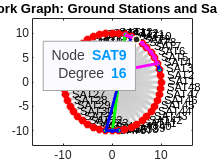

for ii = 1:length(simulation_result_1(:,2))
Data_Transmission_Sequence_1(ii,:) =[satellite_x(simulation_result_1(ii,2)), satellite_y(simulation_result_1(ii,2))];
end

% Plot the graph of data transmission sequence
plot(Data_Transmission_Sequence_1(:,1),Data_Transmission_Sequence_1(:,2),'go', 'MarkerSize', 3, 'MarkerFaceColor', 'G')
plot(Data_Transmission_Sequence_1(:,1),Data_Transmission_Sequence_1(:,2),'g','LineWidth',2);


for ii = 1:length(simulation_result_2(:,2))
Data_Transmission_Sequence_2(ii,:) =[satellite_x(simulation_result_2(ii,2)), satellite_y(simulation_result_2(ii,2))];
end

% Plot the graph of data transmission sequence
plot(Data_Transmission_Sequence_2(:,1),Data_Transmission_Sequence_2(:,2),'bo', 'MarkerSize', 3, 'MarkerFaceColor', 'G')
plot(Data_Transmission_Sequence_2(:,1),Data_Transmission_Sequence_2(:,2),'b','LineWidth',2);


for ii = 1:length(simulation_result_3(:,2))
Data_Transmission_Sequence_3(ii,:) =[satellite_x(simulation_result_3(ii,2)), satellite_y(simulation_result_3(ii,2))];
end

% Plot the graph of data transmission sequence
plot(Data_Transmission_Sequence_3(:,1),Data_Transmission_Sequence_3(:,2),'mo', 'MarkerSize', 3, 'MarkerFaceColor', 'G')
plot(Data_Transmission_Sequence_3(:,1),Data_Transmission_Sequence_3(:,2),'m','LineWidth',2);

hold off

% Adjust the axis limits to fit the plot
axis equal;
title('Network Graph: Ground Stations and Satellites');